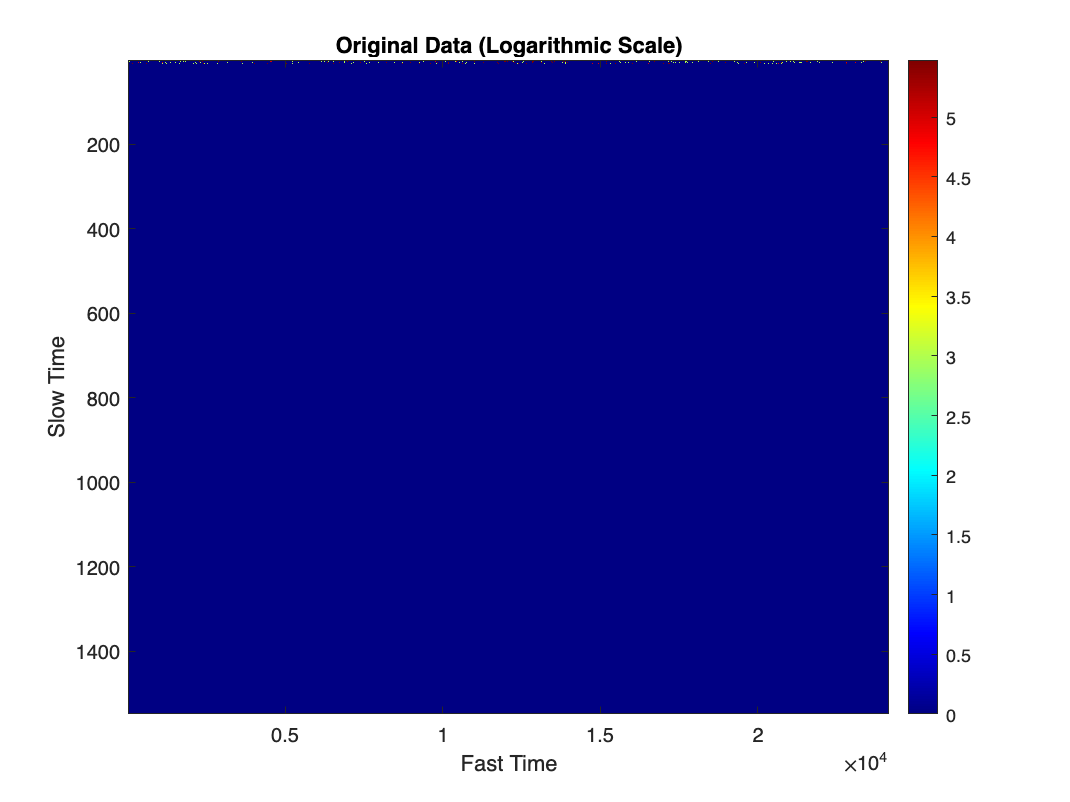


folder_path = '/Users/khavishgovind/Documents/Git_Repos/SAR_Radar_RIT/Matthias_Decoder/Basic_Programs/Csv_Files';
file_path = fullfile(folder_path, 'Mipur_radar_data.csv');
radar_data = readmatrix(file_path);

% Check if the data is complex and take the magnitude
radar_data_magnitude = abs(radar_data);  % Get the magnitude if the data is complex

% Apply logarithm to the magnitude (dB scale)
radar_data_log = 10 * log10(radar_data_magnitude);

% Create a new figure window
figure;  % This opens a new figure window

% Plotting the data
imagesc(radar_data_log);  % Display the data as an image
colormap('jet');  % Use 'jet' colormap for better contrast
colorbar;  % Add a color bar

% Labeling
xlabel('Fast Time');
ylabel('Slow Time');
title('Original Data (Logarithmic Scale)');

% Adjust axis settings for better visualization
axis tight;